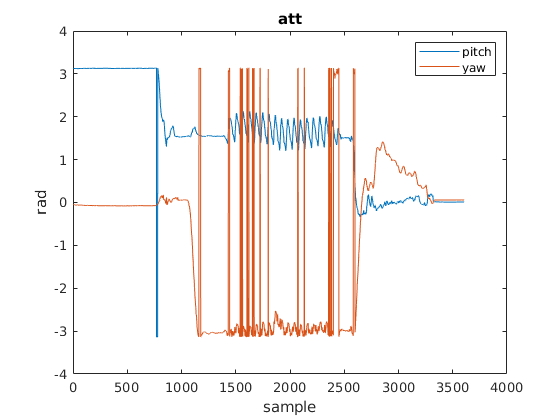

 clear,
% close all,
clc

 addpath('/home/lab5254/Desktop/')
 
bag = rosbag('2019-08-04-16-28-47.bag');



figure
imuSel = select(bag,'Topic','/imu/rpy/complementary_filtered');
imuts = timeseries(imuSel,'Vector.X','Vector.Z');
rpy=[imuts.Data];
plot(rpy)

legend('pitch','yaw'),title('att');xlabel('sample');ylabel('rad')

SL = (select(bag,'Topic','/PDR_SL'));
SLts = timeseries(SL,'X');
deltaH=[SLts.Data];


para_a = (select(bag,'Topic','/parameter'));
% para_a=readMessages(para_a);
% a = para_a{1,1}.X;
% b = para_a{1,1}.Y*0.65;
parats = timeseries(para_a,'X','Y');
slope = [parats.Data];

% kalman = select(bag,'Topic','/kalman_position');
% kalmants = timeseries(kalman,'X','Y');
% hold on;
% kalmantsts=[kalmants.Data];
% plot(-kalmantsts(:,2)/100,kalmantsts(:,1)/100,'.')

close
h=figure

h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


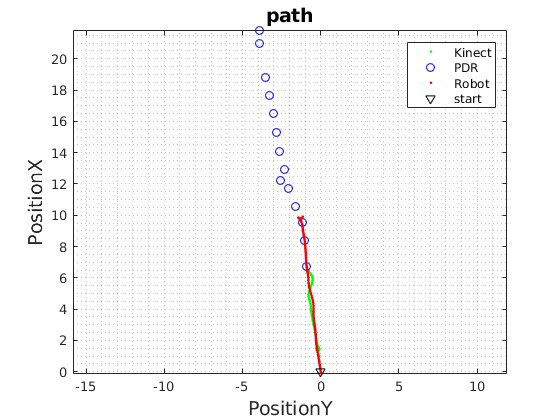

body = select(bag,'Topic','/wp');
bodyts = timeseries(body,'X','Y');
bodyts=[bodyts.Data];
plot(-bodyts(1:439,2),bodyts(1:439,1),'g.'),grid minor,axis equal,hold on



pdrpoint = select(bag,'Topic','/addgoal_point');
pdrts = timeseries(pdrpoint,'X','Y');
pdrts=[pdrts.Data];
plot(-pdrts(1:end,2),pdrts(1:end,1),'bo')

%
% totalpath=[bodyts;pdrts];
odom = select(bag,'Topic','/odom');
odomts = timeseries(odom,'Pose.Pose.Position.X','Pose.Pose.Position.Y');
odomts=[odomts.Data];
plot(-odomts(:,2),odomts(:,1),'r.')

 
plot(0,0,'kv')
% plot(-bodyts(end,2),bodyts(end,1),'kx')
legend('Kinect','PDR','Robot','start')%,'end')
% legend('kinect','Robot','start','end')
title('path','FontSize',14)
xlabel('PositionY','FontSize',14); ylabel('PositionX','FontSize',14)

%  saveas(h,'14-46-29path','jpg')
%  saveas(h,'14-46-29path','fig')

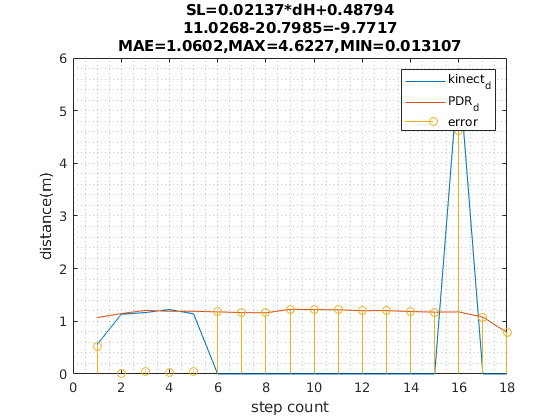



n = 1;
f=figure;
cali = select(bag,'Topic','/calibration_b');
calits = timeseries(cali,'X','Y','Z');
datab=[calits.Data];
plot(datab(n:end,1:2)),hold on,grid minor

ktoatal=sum(abs(calits.Data(n:end,1)));
ptotal = sum(abs(calits.Data(n:end,2)));
ERROR = abs(datab(n:end,1)-datab(n:end,2));
avgerror = mean(ERROR(1:end));
MAX_ERROR = max(ERROR(1:end));
MIN_ERROR = min(ERROR(1:end));
stem(ERROR(1:end))
legend('kinect_d','PDR_d','error'), xlabel('step count'), ylabel('distance(m)')
title({['SL=',num2str(slope(1,1)),'*dH+',num2str(slope(1,2))];[num2str(ktoatal),'-',num2str(ptotal),'=',num2str(ktoatal-ptotal)];['MAE=',num2str(avgerror),',MAX=',num2str(MAX_ERROR),',MIN=',num2str(MIN_ERROR)]})

%  saveas(f,'7-15-11-30-12(7)','jpg')
%  saveas(f,'7-15-11-30-12(7)','fig')